# **The 10-Armed Testbed**

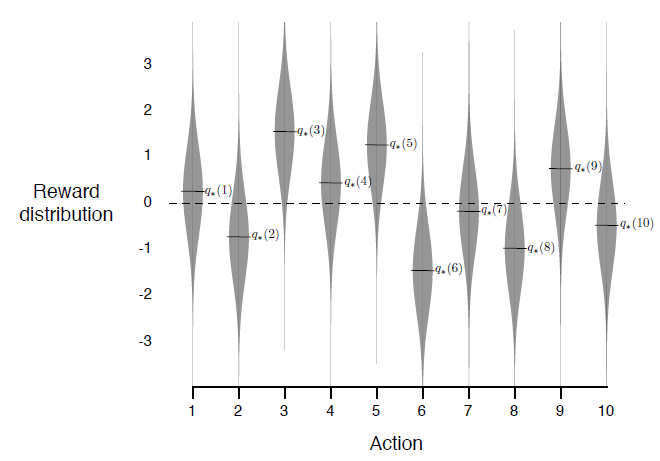

Prueba utilizada para probar los algoritmos simples explicados en el capítulo 2 del libro *"Reinforcement Learning, An Introduction"* de Sutton & Barto. En esta "testbed" tenemos 10 "brazos" (arms) o valores de acción $q_* \left(a\right)$. Cada uno de estos consiste de una posible acción que puede tomar el agente. Se permite que el algoritmo corra durante 1000 iteraciones. Para obtener el comportamiento promedio del algoritmo se repite este proceso 2000 veces.

clear;
IteracionesMax = 1000;
MaxRuns = 2000;

## Opciones Simulación

El usuario puede elegir opciones como: 

- El tipo de método de selección de acción a utilizar

- El tipo de time step a utilizar

- Tipo de valores iniciales

% Método de selección de acción a utilizar: 
% - "Epsilon Greedy"
% - "UCB"
MetodoSeleccion = "Epsilon Greedy";

switch MetodoSeleccion
    
    % Sweep de valores de Epsilon
    case "Epsilon Greedy"    
        Params = [0.1 0.01 0]';
        
    case "UCB"
        Params = [1 2]';
    
    otherwise
        Params = 1;
        
end

% Time step a utilizar:
% - "Constante"
% - "Sample Average"
TipoTimeStep = "Sample Average";

% Valores iniciales a utilizar:
% - "Optimistic"
% - "Realistic"
TipoValorInicial = "Realistic";

## Creación de Loops

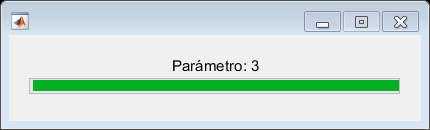

% Sumatoria de las recompensas obtenidas a lo largo de todas las "Runs"
RSum = zeros(IteracionesMax, size(Params,1));
RPromedio = RSum;

% Creación de "Progress Bar" para ver como van los análisis
ProgressBar = waitbar(0,'Espere...');

% Sweep de parámetros
for NoParam = 1:size(Params,1)
    
    waitbar(0, ProgressBar, "Parámetro: " + num2str(NoParam));
    
    % Inicio de una "Run"
    for Run = 1:MaxRuns

## Valor Real de Acciones

El valor real de tomar cada acción se selecciona de manera aleatoria de acuerdo a una distribución normal gaussiana con $\mu =0$ y $\sigma =1$.

        Arms = 10;
        Mu = 0; Sigma = 1;
        
        % Valor Real de la Acción (q*)
        q = normrnd(Mu, Sigma, [Arms, 1]);

## "Bandit Algorithm"

El resto del "bandit algorithm" se implementa de la siguiente manera

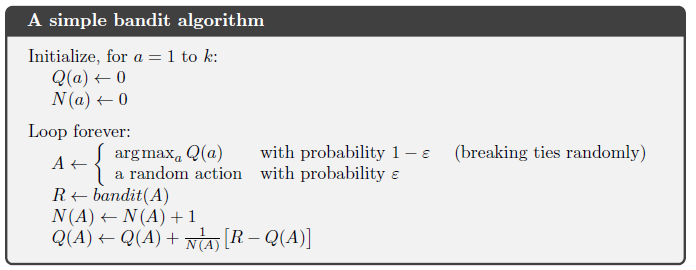

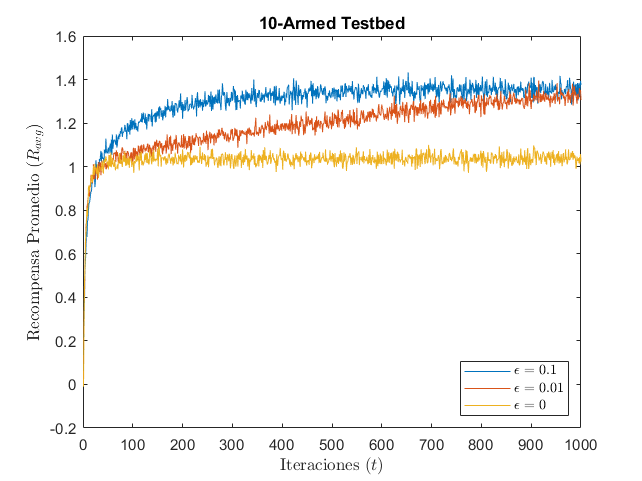

        % Inicialización de Estimados
        switch TipoValorInicial
            case "Optimistic"
                Q = ones(size(q)) * 5;
                
            case "Realistic"
                Q = zeros(size(q));
        end
        
        
        % Inicialización de contadores de toma de una acción (Contadores que
        % incrementan en 1 cada vez que se toma una acción).
        N = zeros(size(q));
        

        % Historial de todas las recompensas obtenidas
        RHistory = zeros(IteracionesMax,1);
        
        % Loop. Idealmente debería de repetirse infinitamente. En este caso se
        % repite "IteracionesMax" veces.
        for TimeStep = 1:IteracionesMax
            
            % Selección de acción
            switch MetodoSeleccion
                case "Epsilon Greedy"
                    
                    % Epsilon: Probabilidad de Explorar en lugar de Explotar
                    Epsilon = Params(NoParam);
                    
                    Probabilidad = unifrnd(0,1);
                    
                    % Probabilidad: (1 - Epsilon) / Explotation
                    if Probabilidad > Epsilon
                        
                        % Se selecciona la "Greedy Action" o la acción con el mayor estimado
                        %A = argmax(Q);
                        [~,A] = max(Q);
                    
                    % Probabilidad: Epsilon / Exploration
                    else
                        
                        % Se selecciona una acción al azar
                        A = randi([1 Arms]);
                        
                    end
                    
                case "UCB"
                    
                    % c: Parámetro que controla el grado de exploración
                    c = Params(NoParam);
                    
                    % Selección de acción basado en 
                    LimiteSuperior = Q + c*sqrt(log(TimeStep) ./ N);
                    [~,A] = max(LimiteSuperior');
                    
            end
                    
            % Cálculo de la recompensa por la acción tomada. 
            R = Bandit(q,A);
            
            % Se guarda la recompensa actual en un historial para cada iteración
            RHistory(TimeStep) = R;
            
            % Actualización del número de veces que se ha tomado la acción
            N(A) = N(A) + 1;
            
            % Cálculo del time-step
            switch TipoTimeStep
                case "Constante"
                    Alpha = 1;
                    
                case "Sample Average"
                    Alpha = 1 / N(A); 
                    
            end
            
            % Actualización del estimado del valor de la acción
            Q(A) = Q(A) + Alpha * (R - Q(A));
        
        end
        
        RSum(:,NoParam) = RSum(:,NoParam) + RHistory;
        waitbar(Run / MaxRuns);
    end
    
    RPromedio(:,NoParam) = RSum(:,NoParam) / MaxRuns;

end

## Graficación de Resultados

figure(1); clf; grid on; grid minor;
plot(RPromedio); 
title("10-Armed Testbed");
ylabel("Recompensa Promedio ($R_{avg}$)", "Interpreter","latex");
xlabel("Iteraciones ($t$)", "Interpreter","latex");

switch MetodoSeleccion
    case "Epsilon Greedy"
        legend("$\epsilon$ = " + num2str(Params(1)), ...
               "$\epsilon$ = " + num2str(Params(2)), ...
               "$\epsilon$ = " + num2str(Params(3)), ...
               "Location","southeast",'Interpreter','latex');
           
   case "UCB"
    legend("$c$ = " + num2str(Params(1)), ...
           "$c$ = " + num2str(Params(2)), ...
           "Location","southeast",'Interpreter','latex');
    
end

## Funciones

#### Bandit(q,A)

Función que calcula la recompensa dada a los agentes. La distribución de la recompensa consiste de una distribución normal con media en el valor real de la acción ($q_* \left(a\right)$) y varianza de 1. 

function R = Bandit(q, A)
    
    Sigma = 1;
    R = normrnd(q(A), Sigma);

end

#### Argmax(q)

Matlab cuenta con una función "max()" que es capaz de retornar el índice del elemento de mayor valor en un array. A pesar de esto, si existen empates entre 2 o más valores, la función retorna el índice del primer valor. Esto puede crear un sesgo innecesario en aplicaciones de q-learning. Para evitar esto se optó a crear una función personalizada que elija de manera aleatoria entre todos los índices que empatan. 

function A = argmax(Q)
    
    Ind = 1:numel(Q);
    ValMax = max(Q);
    IndMax = nonzeros(Ind .* (Q == ValMax));
    A = IndMax(randi(numel(IndMax)));

end